例 2-14

syms z k
G=[0,1;-0.2,-0.9];
Fz=(inv(z*eye(2)-G))*z;
Fk=iztrans(Fz,z,k);
Fk=simplify(Fk)

$$Fk = \left(\begin{array}{cc} 5\,{\left(-\frac{2}{5}\right)}^{k}-4\,{\left(-\frac{1}{2}\right)}^{k} & 10\,{\left(-\frac{2}{5}\right)}^{k}-10\,{\left(-\frac{1}{2}\right)}^{k}\\ 2\,{\left(-\frac{1}{2}\right)}^{k}-2\,{\left(-\frac{2}{5}\right)}^{k} & 5\,{\left(-\frac{1}{2}\right)}^{k}-4\,{\left(-\frac{2}{5}\right)}^{k} \end{array}\right)$$

例 2-15

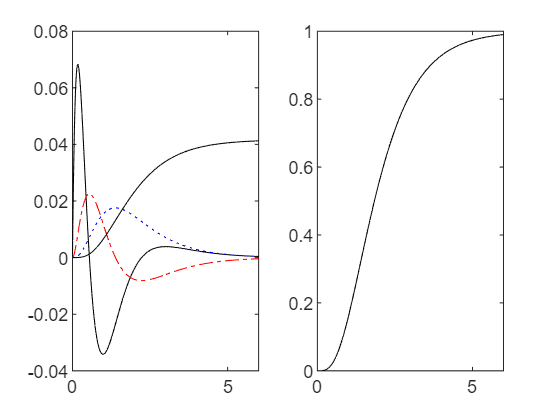

x0=[0;0;0;0];
t0=0;tf=6;tspan=[t0,tf];
[t,x]=ode45('ode_e',tspan,x0);
y=24*x(:,4);
subplot(1,2,1);
plot(t,x(:,1),'k',t,x(:,2),'-.r',t,x(:,3),':b',t,x(:,4),'-k')
subplot(1,2,2);
plot(t,y,'k')